# Di�fferential geometry based edge detection

Observation and explanation based on generated images

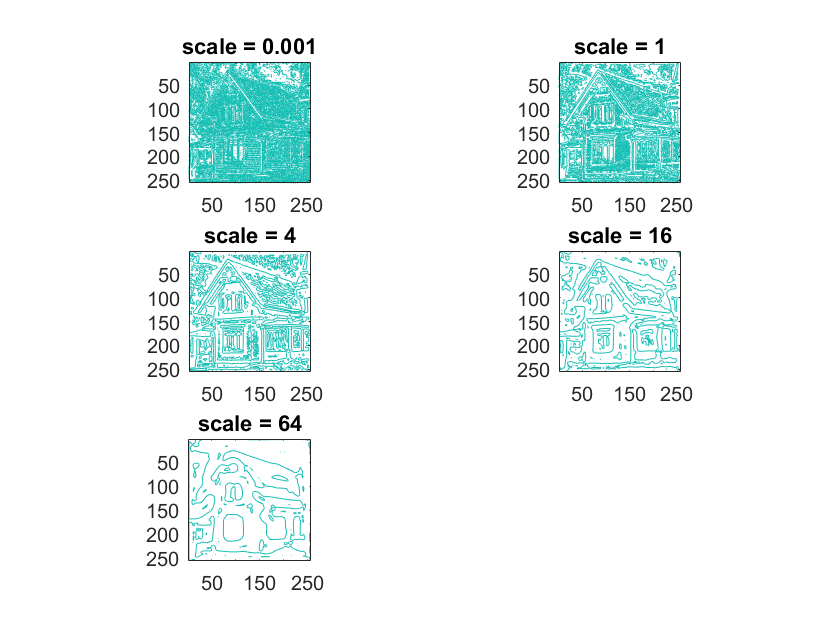

scale = 0.001
scale = 1
scale = 4
scale = 16
scale = 64


%load the image
house = godthem256;

figure;
title('Zero crossings of the second derivative');
scale_array = [0.001, 1.0, 4.0, 16.0, 64.0];
i = 1;
for scale = scale_array
    subplot(3,2,i);
    contour(Lvvtilde(discgaussfft(house, scale),'same'), [0 0]);
    title(['scale = ', num2str(scale)]);
    axis('image');
    axis('ij');
    i = i + 1;
end

Study the sign of the third order derivative in the gradient direction by loading the image* tools = few256;*

and show the result of *showgrey(Lvvvtilde(discgaussfft(tools, scale), 'same') < 0)*

for the same values of scale. What is the e�ffect of the sign condition in this di�fferential expression?

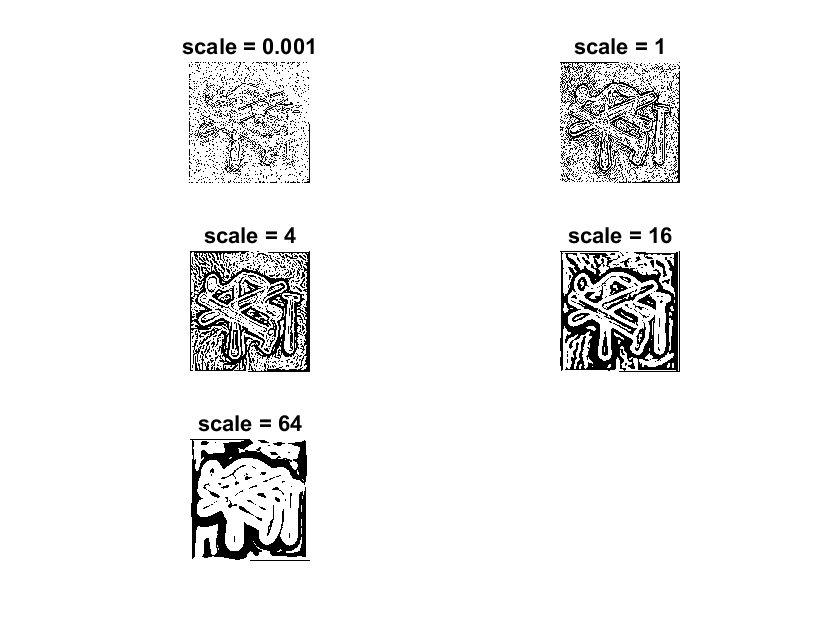

%load the image
tools = few256;

figure;
title('Zero crossings of the second derivative');
scale_array = [0.001, 1.0, 4.0, 16.0, 64.0];
i = 1;
for scale = scale_array
    subplot(3,2,i);
    showgrey(Lvvvtilde(discgaussfft(tools, scale),'same') < 0);
    title(['scale = ', num2str(scale)]);
    axis('image');
    axis('ij');
    i = i + 1;
end

How can you use the response from ~Lvv to detect edges, and how can you improve the result by using ~Lvvv?

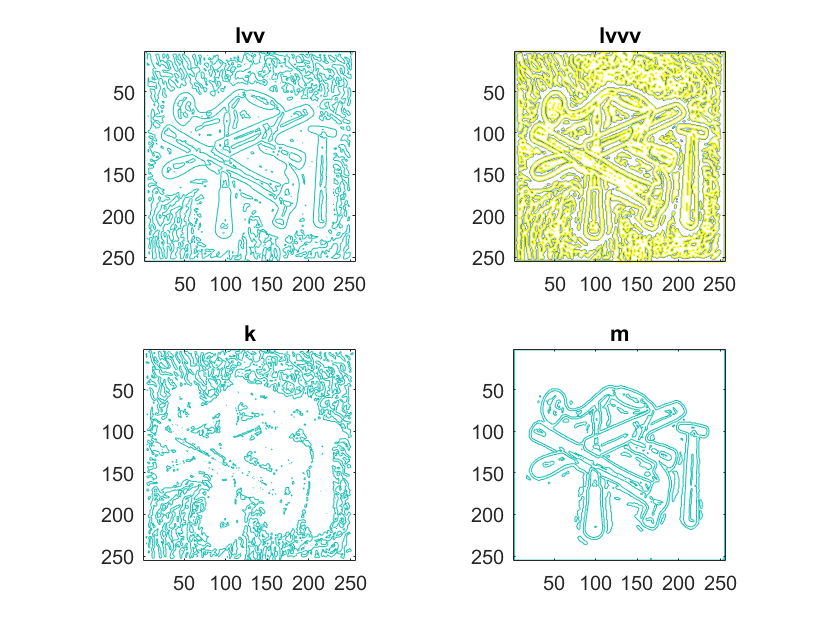

clear;
%load the image
tools = few256;

figure;

%considering only one variance, arbitrarily of 4.
%scale_array = [0.001, 1.0, 4.0, 16.0, 64.0];
scale = 4;
%i = 1;
lvv = Lvvtilde(discgaussfft(tools, scale),'same');
lvvv = Lvvvtilde(discgaussfft(tools, scale),'same');
%for scale = scale_array
subplot(2,2,1);
contour(lvv, [0 0]);
title('lvv');
axis('image');
axis('ij');
%    i = i + 1;
%end

subplot(2,2,2);
contour((lvvv < 0)); 
title('lvvv');
axis('image');
axis('ij');

subplot(2,2,3);
k = log(1 + lvv .* (lvvv<0));
contour(real(k), [0 0]);
title('k');
axis('image');
axis('ij');

subplot(2,2,4);
m = lvv .* k;
contour(real(m), [0 0]);
title('m');
axis('image');
axis('ij');